# Kutta-Joukowski Theorem

This example builds on the example [PotentialFlows.mlx](matlab:open('./PotentialFlows.mlx')) to demonstrate an important theorem relating the vortex strength, also called circulation, in a flow around a body to the lift on the body.  

## Vortex in uniform flow

First we demonstrate that a vortex in uniform flow produces lift matching the Kutta-Joukowski Theorem.  This theorem states that:

$\textrm{Lift}=\rho_{\infty } V_{\infty } \Gamma$, where $\Gamma$ is the circulation from the vortex.

(See [https://en.wikipedia.org/wiki/Kutta%E2%80%93Joukowski_theorem](https://en.wikipedia.org/wiki/Kutta%E2%80%93Joukowski_theorem) )

### Define the vortex flow

Similar to the previous example, we define potential flow for uniform flow plus a vortex.   Our goal is to demonstrate the Kutta-Joukowski Theorem by integrating the integral conservation of moment equation about a control surface of radius $R_1$.

syms r theta R_1 rho_inf V_inf V_r V_theta Gamma

V_r = V_inf*cos(theta)

$$V\_r = V_{\inf}\,\cos\left(\theta \right)$$

V_theta = -V_inf*sin(theta) - Gamma/(2*pi*r)

$$V\_theta = -V_{\inf}\,\sin\left(\theta \right)-\frac{\Gamma }{2\,r\,\pi }$$

V_z = simplify(V_r*sin(theta)+V_theta*cos(theta))

$$V\_z = -\frac{\Gamma \,\cos\left(\theta \right)}{2\,r\,\pi }$$

### Integrate the Z-momentum equation

We want to integrate the conservation of momentum for ideal irrotational flow, which leaves just the vertical flux of momentum and the force from pressure on the control surface:


$$Z\;\textrm{momentum}\;\textrm{equation}:\;\oint_{\textrm{CS}} \rho_{\infty } \;V_z \;\;\left(\vec{V} \cdot \widehat{n} \right)\;\textrm{dS}=\oint_{\textrm{CS}} -P\left(\widehat{k} \cdot \widehat{n} \right)\;\textrm{dS}$$


We need to define a control surface for integration, using a circle of radius $R_1$, with a cut on the positive $x$-axis, and excluding the origin.  The normal vector on this circle points inward (into the fluid), so $\vec{V} \cdot \widehat{n}$ is equal to $-V_r$ , and $\textrm{dS}=R_1 \;d\theta$ .  The net flux on the x-axis and origin is zero.

First, let's integrate the term on the left, which is the momentum flux term:

% Compute the integrand for the flux integral
dFzMom = rho_inf*V_z*(-1)*V_r % *dS

$$dFzMom = \frac{\Gamma \,V_{\inf}\,\rho_{\inf}\,{\cos\left(\theta \right)}^{2}}{2\,r\,\pi }$$

% Integrate around the circle of radius R_1
FzMom = int(subs(dFzMom,{r},{R_1})*R_1,theta,0,2*pi)

$$FzMom = \frac{\Gamma \,V_{\inf}\,\rho_{\inf}}{2}$$

Interesting!  It seems to be only half of the expected lift, $\rho_{\infty } V_{\infty } \Gamma$, based on the Kutta-Joukowski theorem   Regardless, where is this lift coming from?  Let's plot the components of the integral as a function of theta.

We can assume some values for the constants, and plot $V_z$, $V_r$, and the product $V_z\cdot V_r$.

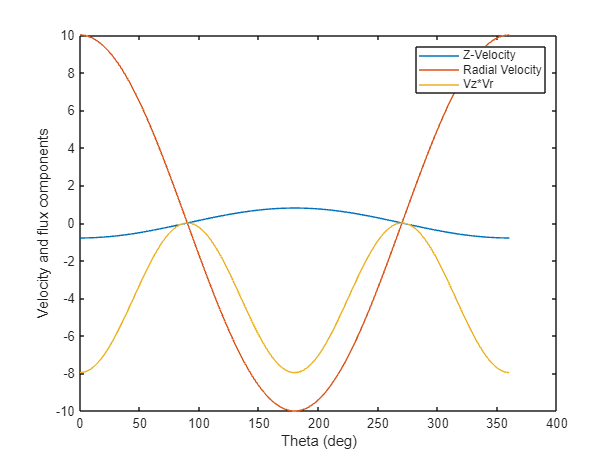

thetaVals = linspace(0,2*pi,360);
VzVals = double(subs(V_z,{theta,Gamma,rho_inf,V_inf,r},{thetaVals,50.0,1.0,10.0,10.0}));
VrVals = double(subs(V_r,{theta,Gamma,rho_inf,V_inf,r},{thetaVals,50.0,1.0,10.0,10.0}));
VzVrVals = VzVals.*VrVals;
plot(180.0/pi*thetaVals,VzVals)
hold on
plot(180.0/pi*thetaVals,VrVals)
hold on
plot(180.0/pi*thetaVals,VzVrVals)
xlabel("Theta (deg)")
ylabel("Velocity and flux components")
legend(["Z-Velocity", "Radial Velocity", "Vz*Vr"])
hold off

Notice that the product of Vz and Vr has highest magnitude at $\theta=0^{\circ}$ and $360^{\circ}$ (downstream) and $\theta=180^{\circ}$ (upstream), while the product goes to zero at $90^{\circ}$ and $270^{\circ}$ (top and bottom).  Also notice that at $\theta=0^{\circ}$, $V_z$ is negative ("downwash") while at $\theta=180^{\circ}$, $V_z$ is positive ("upwash").  From this we learn that the momentum flux is seen as upwash in front of the body and downwash behind the body, of the same magnitude as the upwash.

### Contribution from Pressure 

One thing we are missing from our calculation so far is the pressure force which is exerted on the outer control surface. Let's calculate the pressure at radius $R_1$, and the vertical component of pressure force.  

Bernoulli's equation gives us the formula for pressure coefficient $C_P$ as:

C_P = 1 - (V_r^2 + V_theta^2) / V_inf^2

$$C\_P = 1-\frac{{V_{\inf}}^{2}\,{\cos\left(\theta \right)}^{2}+{\left(V_{\inf}\,\sin\left(\theta \right)+\frac{\Gamma }{2\,r\,\pi }\right)}^{2}}{{V_{\inf}}^{2}}$$

We can obtain pressure, $P$, from the pressure coefficient using:


$$P=\frac{1}{2}\rho_{\infty } V_{\infty }^2 \;C_P +P_{\infty }$$


Integrating the vertical component of the pressure force on the control surface, we have to multiply $C_P$ by $\frac{1}{2}\rho_{\infty } V_{\infty }^2$ and apply the pressure force on an element of area, $dS = R_1 d\theta \cdot (1)$, for unit span.  The pressure applies as force toward the surface, and the surface normal is into the fluid, so the minus signs cancel.  Projecting in the vertical direction produces $dS = R_1\sin(\theta)\; d\theta$.

% Compute the integrand for the Z force from pressure on a circle
dFzP1 = (1/2)*rho_inf*V_inf^2*C_P*sin(theta) % *dS

$$dFzP1 = -\frac{{V_{\inf}}^{2}\,\rho_{\inf}\,\sin\left(\theta \right)\,\left(\frac{{V_{\inf}}^{2}\,{\cos\left(\theta \right)}^{2}+{\left(V_{\inf}\,\sin\left(\theta \right)+\frac{\Gamma }{2\,r\,\pi }\right)}^{2}}{{V_{\inf}}^{2}}-1\right)}{2}$$

dFzP1 = simplify(expand(dFzP1))

$$dFzP1 = -\frac{\Gamma \,\rho_{\inf}\,\sin\left(\theta \right)\,\left(\Gamma +4\,\pi \,V_{\inf}\,r\,\sin\left(\theta \right)\right)}{8\,r^{2}\,\pi^{2}}$$


% Integrate for a circle of radius R_1
FzP1 = int(subs(dFzP1,{r},{R_1})*R_1,theta,0,2*pi)

$$FzP1 = -\frac{\Gamma \,V_{\inf}\,\rho_{\inf}}{2}$$

we see that there is a pressure force acting on the outer control surface that creates the other half of the lift!  The lift of a fictitious body at the origin (responsible for creating the circulation) would be:

Lift = FzMom - FzP1

$$Lift = \Gamma \,V_{\inf}\,\rho_{\inf}$$

which satisfies the Kutta-Joukowski Theorem.  We can plot the pressure contribution to see where it is largest:

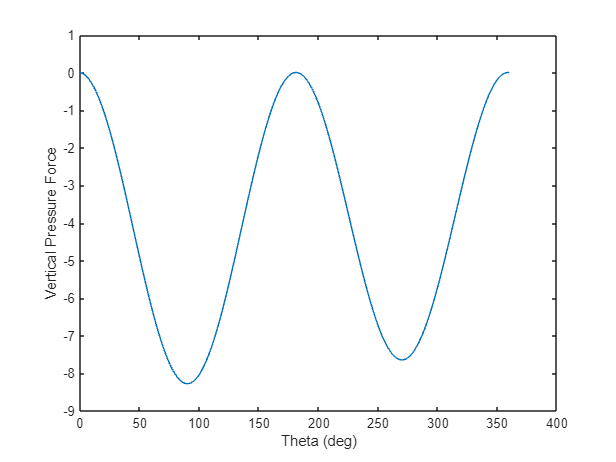

FzP1Vals = double(subs(dFzP1,{theta,Gamma,rho_inf,V_inf,r},{thetaVals,50.0,1.0,10.0,10.0}));
plot(180.0/pi*thetaVals,FzP1Vals)
xlabel("Theta (deg)")
ylabel("Vertical Pressure Force")

The pressure force has negative peaks at $\theta=90^{\circ}$ (top) and $270^{\circ}$ (bottom), with different values.  The net integral in pressure force comes from the pressure force difference at top and bottom surfaces, which creates a net lift on the control surface.  This net lift from pressure difference above and below the body is the same magnitude as the lift from upwash/downwash (momentum flux in front of / behind the body). 

## Flow over a rotating cylinder

Next let's add in a cylinder of radius $R_0$.  Our expectation is that adding the body, via a doublet, does not change the circulation or the explanation of lift.  However, it does give us a chance to calculate the lift on the body surface.

syms R_0
V_r = (1 - R_0^2/r^2) * V_inf*cos(theta)

$$V\_r = -V_{\inf}\,\cos\left(\theta \right)\,\left(\frac{{R_{0}}^{2}}{r^{2}}-1\right)$$

V_theta = -(1 + R_0^2/r^2) * V_inf*sin(theta) - Gamma/(2*pi*r)

$$V\_theta = -\frac{\Gamma }{2\,r\,\pi }-V_{\inf}\,\sin\left(\theta \right)\,\left(\frac{{R_{0}}^{2}}{r^{2}}+1\right)$$

V_z = simplify(V_r*sin(theta)+V_theta*cos(theta))

$$V\_z = -\frac{\cos\left(\theta \right)\,\left(4\,V_{\inf}\,\pi \,\sin\left(\theta \right)\,{R_{0}}^{2}+\Gamma \,r\right)}{2\,r^{2}\,\pi }$$

C_P = simplify(1 - (V_r^2 + V_theta^2) / V_inf^2)

$$C\_P = 1-\frac{{\left(\frac{\Gamma }{2\,r\,\pi }+V_{\inf}\,\sin\left(\theta \right)\,\left(\frac{{R_{0}}^{2}}{r^{2}}+1\right)\right)}^{2}+{V_{\inf}}^{2}\,{\cos\left(\theta \right)}^{2}\,{\left(\frac{{R_{0}}^{2}}{r^{2}}-1\right)}^{2}}{{V_{\inf}}^{2}}$$

The pressure distribution on the cylinder surface is:

C_P0 = expand(subs(C_P,{r},{R_0}))

$$C\_P0 = 1-\frac{\Gamma^{2}}{4\,{R_{0}}^{2}\,{V_{\inf}}^{2}\,\pi^{2}}-\frac{2\,\Gamma \,\sin\left(\theta \right)}{R_{0}\,V_{\inf}\,\pi }-4\,{\sin\left(\theta \right)}^{2}$$

This time we have a surface for the cylinder.  Let's calculate the lift on the surface per unit span.  The pressure is acting in the direction toward the surface, and the surface normal is outward, yielding a minus sign on the pressure.

FzP0 = (1/2)*rho_inf*V_inf^2*R_0*int(-C_P0*sin(theta),theta,0,2*pi)

$$FzP0 = \Gamma \,V_{\inf}\,\rho_{\inf}$$

### Integrate the Z-momentum equation

Great, the force on cylinder surface matches the Kutta-Joukowski theorem.  Now let's calculate the integrals at the outer control surface

FzMom = int(rho_inf*subs(V_z,{r},{R_1})*(-1)*subs(V_r,{r},{R_1})*R_1,theta,0,2*pi)

$$FzMom = -\frac{\Gamma \,V_{\inf}\,\rho_{\inf}\,\left({R_{0}}^{2}-{R_{1}}^{2}\right)}{2\,{R_{1}}^{2}}$$

In the limit as $R_1$ goes to infinity, while $R_0$ stays the same, this matches Kutta-Joukowski except for a factor of 2.  Does the pressure force on the outer control surface add the missing half?

### Contribution from Pressure 

FzP1 = (1/2)*rho_inf*V_inf^2*R_1*int(subs(C_P,{r},{R_1})*sin(theta),theta,0,2*pi)

$$FzP1 = -\frac{\Gamma \,V_{\inf}\,\rho_{\inf}\,\left({R_{0}}^{2}+{R_{1}}^{2}\right)}{2\,{R_{1}}^{2}}$$

Lift = FzMom - FzP1

$$Lift = \frac{\Gamma \,V_{\inf}\,\rho_{\inf}\,\left({R_{0}}^{2}+{R_{1}}^{2}\right)}{2\,{R_{1}}^{2}}-\frac{\Gamma \,V_{\inf}\,\rho_{\inf}\,\left({R_{0}}^{2}-{R_{1}}^{2}\right)}{2\,{R_{1}}^{2}}$$

Lift = simplify(Lift)

$$Lift = \Gamma \,V_{\inf}\,\rho_{\inf}$$

Yes actually the pressure force on the outer boundary provides exactly the needed lift, so that 

"Z-Momentum Flux" = Lift + "Force on the outer surface".

## Integrate on square control volume

How does the integration work if we use a square control volume instead?  Let's use $R_1$ now as the half-width of a control volume, $x$ and $z$ go from $(-R_1,R_1)$


$$F_z =\oint_{\textrm{CS}} \rho_{\infty } \;V_z \;\;\left(\vec{V} \cdot \widehat{n} \right)\;\textrm{dS}=\oint_{\textrm{CS}} -P\left(\widehat{k} \cdot \widehat{n} \right)\;\textrm{dS}$$



$$\text{FzMomTop} = \displaystyle \int_{x=-R_1}^{R_1} \rho_{\infty} V_z^2\; dx, \quad \text{at} \quad z=R_1$$



$$\text{FzMomBottom} = \displaystyle \int_{x=-R_1}^{R_1} -\rho_{\infty} V_z^2\; dx, \quad \text{at} \quad z=-R_1$$



$$\text{FzMomLeft} = \displaystyle \int_{z=-R_1}^{R_1} -\rho_{\infty} V_zV_x \; dz, \quad \text{at} \quad x=-R_1$$



$$\text{FzMomRight} = \displaystyle \int_{z=-R_1}^{R_1} \rho_{\infty} V_zV_x\; dz, \quad \text{at} \quad x=R_1$$


### Back to vortex plus uniform flow

Previously, we showed we don't actually need the cylinder to see the effect of lift on the control surface.  This time we will calculate the velocity components in Cartesian coordinates (after first showing them in polar).

% Set velocity components, now including V_x
syms r theta
V_r = V_inf*cos(theta)

$$V\_r = V_{\inf}\,\cos\left(\theta \right)$$

V_theta = -V_inf*sin(theta) - Gamma/(2*pi*r)

$$V\_theta = -V_{\inf}\,\sin\left(\theta \right)-\frac{\Gamma }{2\,r\,\pi }$$

V_x = simplify(V_r*cos(theta)-V_theta*sin(theta))

$$V\_x = \frac{\Gamma \,\sin\left(\theta \right)+2\,\pi \,V_{\inf}\,r}{2\,r\,\pi }$$

V_z = simplify(V_r*sin(theta)+V_theta*cos(theta))

$$V\_z = -\frac{\Gamma \,\cos\left(\theta \right)}{2\,r\,\pi }$$


% Repeat with theta and r substitutions into x and z first
syms x z
assume(x,"real"); % needed when taking square roots, to avoid complex-valued solutions 
assume(z,"real");
r = sqrt(x^2 + z^2)

$$r = \sqrt{x^{2}+z^{2}}$$

theta = atan2(z,x)

$$theta = \text{atan2}\left(z,x\right)$$

V_r = V_inf*cos(theta)

$$V\_r = \frac{V_{\inf}\,x}{\sqrt{x^{2}+z^{2}}}$$

V_theta = -V_inf*sin(theta) - Gamma/(2*pi*r)

$$V\_theta = -\frac{V_{\inf}\,z}{\sqrt{x^{2}+z^{2}}}-\frac{\Gamma }{2\,\pi \,\sqrt{x^{2}+z^{2}}}$$

V_x = simplify(V_r*cos(theta)-V_theta*sin(theta))

$$V\_x = \frac{\Gamma \,z+2\,\pi \,V_{\inf}\,\left(x^{2}+z^{2}\right)}{2\,\pi \,\left(x^{2}+z^{2}\right)}$$

V_z = simplify(V_r*sin(theta)+V_theta*cos(theta))

$$V\_z = -\frac{\Gamma \,x}{2\,\pi \,\left(x^{2}+z^{2}\right)}$$

### Integrate the Z-momentum equation

% Top wall, compute the integrand for the flux integral
dFzMomTop = rho_inf*V_z^2 % *dS

$$dFzMomTop = \frac{\Gamma^{2}\,\rho_{\inf}\,x^{2}}{4\,\pi^{2}\,{\left(x^{2}+z^{2}\right)}^{2}}$$

% Integrate over the line
FzMomTop = int(subs(dFzMomTop,{z},{R_1}),x,-R_1,R_1)

$$FzMomTop = \frac{\Gamma^{2}\,\rho_{\inf}\,\left(\pi -2\right)}{16\,R_{1}\,\pi^{2}}$$

% Bottom wall, compute the integrand for the flux integral
dFzMomBottom = -rho_inf*V_z^2 % *dS

$$dFzMomBottom = -\frac{\Gamma^{2}\,\rho_{\inf}\,x^{2}}{4\,\pi^{2}\,{\left(x^{2}+z^{2}\right)}^{2}}$$

% Integrate over the line
FzMomBottom = int(subs(dFzMomBottom,{z},{-R_1}),x,-R_1,R_1)

$$FzMomBottom = -\frac{\Gamma^{2}\,\rho_{\inf}\,\left(\pi -2\right)}{16\,R_{1}\,\pi^{2}}$$

% Left wall, compute the integrand for the flux integral
dFzMomLeft = rho_inf*V_z*V_x % *dS

$$dFzMomLeft = -\frac{\Gamma \,\rho_{\inf}\,x\,\left(\Gamma \,z+2\,\pi \,V_{\inf}\,\left(x^{2}+z^{2}\right)\right)}{4\,\pi^{2}\,{\left(x^{2}+z^{2}\right)}^{2}}$$

% Integrate over the line
FzMomLeft = int(subs(dFzMomLeft,{x},{-R_1}),z,-R_1,R_1)

$$FzMomLeft = \frac{\Gamma \,V_{\inf}\,\rho_{\inf}}{4}$$

% Right wall, compute the integrand for the flux integral
dFzMomRight = -rho_inf*V_z*V_x % *dS

$$dFzMomRight = \frac{\Gamma \,\rho_{\inf}\,x\,\left(\Gamma \,z+2\,\pi \,V_{\inf}\,\left(x^{2}+z^{2}\right)\right)}{4\,\pi^{2}\,{\left(x^{2}+z^{2}\right)}^{2}}$$

% Integrate over the line
FzMomRight = int(subs(dFzMomRight,{x},{R_1}),z,-R_1,R_1)

$$FzMomRight = \frac{\Gamma \,V_{\inf}\,\rho_{\inf}}{4}$$

% Total momentum integral
FzMom = FzMomLeft + FzMomRight + FzMomTop + FzMomBottom

$$FzMom = \frac{\Gamma \,V_{\inf}\,\rho_{\inf}}{2}$$

Same result as before!  But now more clear that the top and bottom surfaces sum to zero, and the left and right surfaces are equal.  We can see that the left and right integrals are from "upwash" and "downwash" by computing the average value of $V_z$ in each section:

VzUpwash = 1/(2*R_1)*int(subs(V_z,{x},{-R_1}),z,-R_1,R_1)

$$VzUpwash = \frac{\Gamma }{8\,R_{1}}$$

VzDownwash = 1/(2*R_1)*int(subs(V_z,{x},{R_1}),z,-R_1,R_1)

$$VzDownwash = -\frac{\Gamma }{8\,R_{1}}$$

The $z$-velocity is multiplied by $x$-velocity (which is close to $V_{\infty}$) and density in the momentum integral.

### Contribution from Pressure 

What about the pressure contribution?  Recall that the normal direction is pointing into the fluid volume.  The left and right integrals are zero due to the dot product with k.


$$F_z =\oint_{\textrm{CS}} \rho_{\infty } \;V_z \;\;\left(\vec{V} \cdot \widehat{n} \right)\;\textrm{dS}=\oint_{\textrm{CS}} -P\left(\widehat{k} \cdot \widehat{n} \right)\;\textrm{dS}$$



$$\text{FzPTop} = \displaystyle \int_{x=-R_1}^{R_1} P\; dx , \quad \text{at} \quad z=R_1$$



$$\text{FzPBottom} = \displaystyle \int_{x=-R_1}^{R_1} -P\; dx, \quad \text{at} \quad z=-R_1$$



$$\text{FzPLeft} = 0, \quad \text{at} \quad x=-R_1$$



$$\text{FzPRight} = 0, \quad \text{at} \quad x=R_1$$


Also note that $P=\frac{\rho_{\infty } V_{\infty }^2 }{2}\;C_p +P_{\infty }$, and is applied on a surface of area, $S=c \cdot 1$, where the chord, $c$, is $2R_0$, and the span is $1$ (so that forces are "per unit span").  This reference area was already assumed in the definition of $C_P$.

C_P = 1 - (V_x^2 + V_z^2)/V_inf^2

$$C\_P = 1-\frac{\frac{{\left(\Gamma \,z+2\,\pi \,V_{\inf}\,\left(x^{2}+z^{2}\right)\right)}^{2}}{4\,\pi^{2}\,{\left(x^{2}+z^{2}\right)}^{2}}+\frac{\Gamma^{2}\,x^{2}}{4\,\pi^{2}\,{\left(x^{2}+z^{2}\right)}^{2}}}{{V_{\inf}}^{2}}$$

FzPTop = (1/2)*rho_inf*V_inf^2*int(subs(C_P,{z},{R_1}),x,-R_1,R_1)

$$FzPTop = -\frac{\Gamma \,\rho_{\inf}\,\left(\Gamma +4\,\pi \,R_{1}\,V_{\inf}\right)}{16\,R_{1}\,\pi }$$

FzPTop = expand(FzPTop)

$$FzPTop = -\frac{\Gamma \,V_{\inf}\,\rho_{\inf}}{4}-\frac{\Gamma^{2}\,\rho_{\inf}}{16\,R_{1}\,\pi }$$

FzPBottom = -(1/2)*rho_inf*V_inf^2*int(subs(C_P,{z},{-R_1}),x,-R_1,R_1)

$$FzPBottom = \frac{\Gamma \,\rho_{\inf}\,\left(\Gamma -4\,\pi \,R_{1}\,V_{\inf}\right)}{16\,R_{1}\,\pi }$$

FzPBottom = expand(FzPBottom)

$$FzPBottom = \frac{\Gamma^{2}\,\rho_{\inf}}{16\,R_{1}\,\pi }-\frac{\Gamma \,V_{\inf}\,\rho_{\inf}}{4}$$

NetFzP = simplify((FzPTop + FzPBottom))

$$NetFzP = -\frac{\Gamma \,V_{\inf}\,\rho_{\inf}}{2}$$

CpAvgTop = expand(1/(2*R_1)*int(subs(C_P,{z},{R_1}),x,-R_1,R_1))

$$CpAvgTop = -\frac{\Gamma }{4\,R_{1}\,V_{\inf}}-\frac{\Gamma^{2}}{16\,{R_{1}}^{2}\,{V_{\inf}}^{2}\,\pi }$$

CpAvgBottom = expand(1/(2*R_1)*int(subs(C_P,{z},{-R_1}),x,-R_1,R_1))

$$CpAvgBottom = \frac{\Gamma }{4\,R_{1}\,V_{\inf}}-\frac{\Gamma^{2}}{16\,{R_{1}}^{2}\,{V_{\inf}}^{2}\,\pi }$$

The average difference between coefficient of pressure at the top and bottom of the control surface is:

CpDiff = CpAvgTop - CpAvgBottom

$$CpDiff = -\frac{\Gamma }{2\,R_{1}\,V_{\inf}}$$

That is, the pressure above the body is lower than the pressure below the body by an amount proportional to circulation.  The vertical pressure gradient can be viewed as a cause of lift on the body (or perhaps of consequence of the lift).

## Summary of results from integration of momentum equation

We can see that the vortex creates a pressure force at the outer boundary due to Bernoulli's equation.  We see that $C_P$` is reduced above the body and increased below the body by the same amount, proportional to the circulation.

Therefore we can conclude that the lift on a body is matched by two effects at the farfield:

- Upwash and downwash, which are equal in magnitude and seen by the average vertical velocity on left and right boundaries.  It is helpful to view the upwash and downwash effect as "Force = mass*acceleration", meaning that a vertical force must be matched by a change in momentum in the opposite direction.

- A pressure gradient, with $C_P$ above the body reduced by the circulation, and $C_P$ below the body increased by the same amount.  It is helpful to view this pressure as caused by a farfield effect of the pressure distribution on the body.  When you have a high pressure on the body lower surface, it creates a large region of high pressure that can also be felt far below the body, and similarly on the top surface with the low pressure.

## Visualization of Lift Effects

Finally, now that we have some theoretical explanation of the effects of body lift on the control volume, let's create a visualization that shows this effect by plotting $C_P$ and $V_z$ for flow over a lifting cylinder.

Note: this section is self-contained; you can change the parameters below to modify the plots.  

### Flow over a rotating cylinder

syms x z r theta V_inf R_0 R_1 Kappa Gamma
V_inf = 10; % Freestream velocity
rho_inf = 1; % Constant density
R_0 = 1; % Radius of cylinder
R_1 = 5; % Outer radius of control volume
C_l = 8.0; % Specify C_l to get different amounts of lift and circulation

%Calcuate the streamfunction to show the streamlines
% Uniform flow
psi = V_inf*z

$$psi = 10\,z$$

psi = V_inf*r*sin(theta)

$$psi = 10\,r\,\sin\left(\theta \right)$$

% Doublet flow
Kappa = R_0^2*(2*pi*V_inf)

Kappa = 62.8319

psi = psi - Kappa/(2*pi)*sin(theta)/r

$$psi = 10\,r\,\sin\left(\theta \right)-\frac{10\,\sin\left(\theta \right)}{r}$$

% Vortex flow
Gamma = C_l*V_inf*R_0

Gamma = 80

psi = psi + Gamma/(2*pi)*log(r)

$$psi = \frac{1791925356007081\,\log\left(r\right)}{140737488355328}-\frac{10\,\sin\left(\theta \right)}{r}+10\,r\,\sin\left(\theta \right)$$

% Compute the streamline at the body using r=R, and theta=0
psiBody = double(subs(psi,{r,theta},{R_0,0.0}))    

psiBody = 0


% Compute V_r and V_theta
V_theta = -diff(psi,r)

$$V\_theta = -10\,\sin\left(\theta \right)-\frac{10\,\sin\left(\theta \right)}{r^{2}}-\frac{1791925356007081}{140737488355328\,r}$$

V_r = (1/r)*diff(psi,theta)

$$V\_r = -\frac{\frac{10\,\cos\left(\theta \right)}{r}-10\,r\,\cos\left(\theta \right)}{r}$$

% Compute V_z
V_z = simplify(V_r*sin(theta)+V_theta*cos(theta))

$$V\_z = -\frac{\cos\left(\theta \right)\,\left(1791925356007081\,r+2814749767106560\,\sin\left(\theta \right)\right)}{140737488355328\,r^{2}}$$


% Compute C_P
C_P = 1 - (V_theta^2 + V_r^2)/V_inf^2

$$C\_P = 1-\frac{{\left(\frac{10\,\cos\left(\theta \right)}{r}-10\,r\,\cos\left(\theta \right)\right)}^{2}}{100\,r^{2}}-\frac{{\left(10\,\sin\left(\theta \right)+\frac{10\,\sin\left(\theta \right)}{r^{2}}+\frac{1791925356007081}{140737488355328\,r}\right)}^{2}}{100}$$

### Plot the vertical velocity to show upwash/downwash

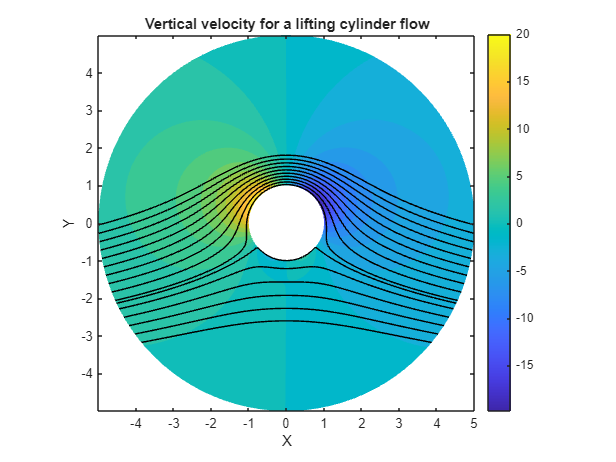

% Create a grid of r,theta values
rVals = linspace(double(R_0),double(R_1),100);
thetaVals = linspace(0,2*pi,100);
[rGrid, thetaGrid] = meshgrid(rVals,thetaVals);
[xGrid, yGrid] = pol2cart(thetaGrid,rGrid);

% Calculate streamfunction for the contour lines
% Calculate V_z to plot the vertical velocity with upwash/downwash effect
psiVals = double(subs(psi, {r, theta}, {rGrid, thetaGrid}));
VzVals = double(subs(V_z, {r, theta}, {rGrid, thetaGrid}));
[~,h] = contourf(xGrid,yGrid,VzVals,25);
h.LineStyle = 'none';
hold on;
contour(xGrid,yGrid,psiVals,linspace(-10,20,15),"-k");
hold on;
contour(xGrid,yGrid,psiVals,[psiBody,psiBody],"-k");
hold off
xlabel("X")
ylabel("Y")
zlabel("V_z")
axis equal
colorbar
title("Vertical velocity for a lifting cylinder flow")

### Plot $C_P$ to show the pressure gradient

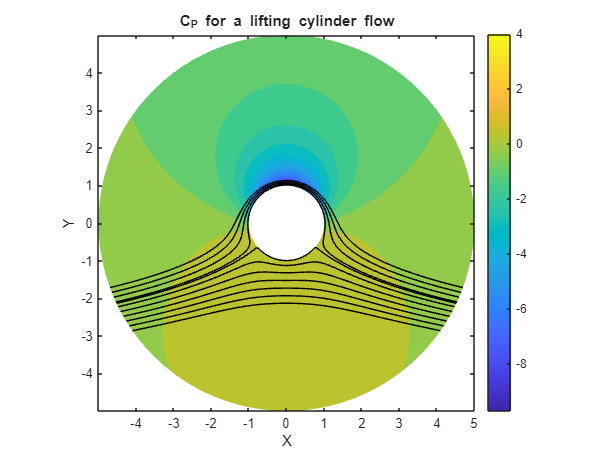

% Calculate C_P to plot the vertical pressure gradient effect
CpVals = double(subs(C_P, {r, theta}, {rGrid, thetaGrid}));
[~,h] = contourf(xGrid,yGrid,CpVals,15);
h.LineStyle = 'none';
hold on;
contour(xGrid,yGrid,psiVals,linspace(-7,4,10),"-k");
hold on;
contour(xGrid,yGrid,psiVals,[psiBody,psiBody],"-k");
hold off
xlabel("X")
ylabel("Y")
zlabel("V_z")
axis equal
colorbar
title("C_P for a lifting cylinder flow")